# 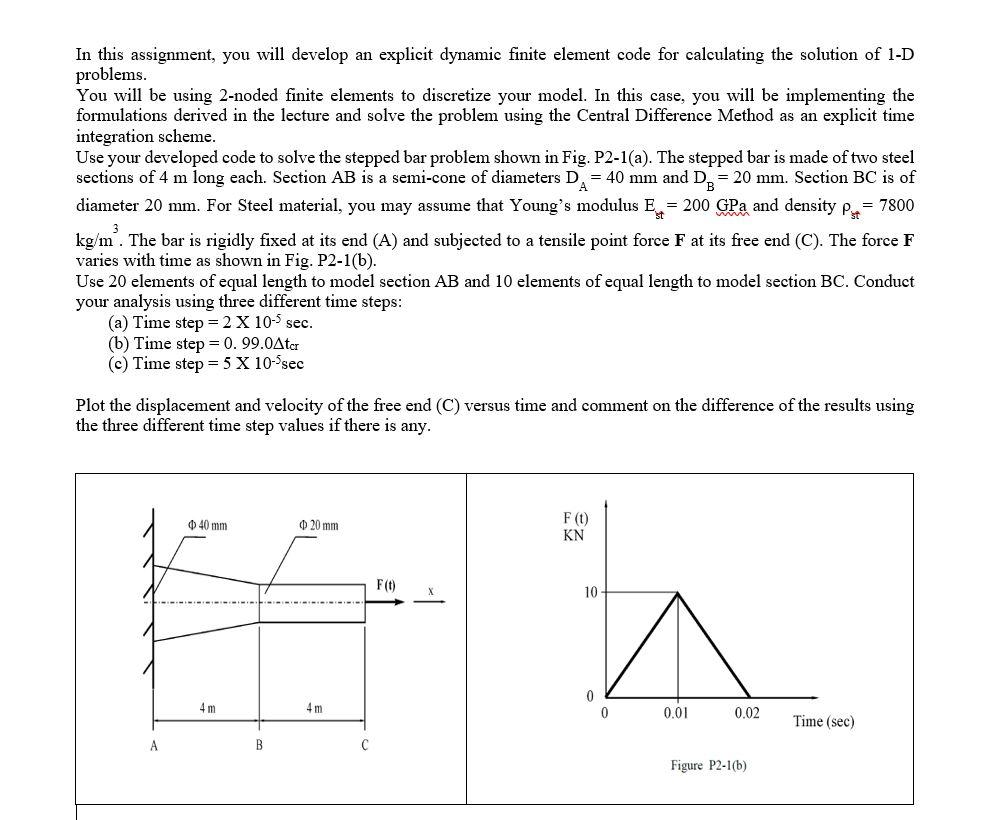

# Explanations:

The explicit dynamic finite element method used in the code below is based on the following mathematical formulations:

**Discretization:** The bar is divided into a finite number of elements, each of which has two nodes. The displacement and velocity at each node are assumed to vary linearly within the element, and are interpolated using shape functions. The element stiffness matrix, mass matrix, and force vector are then computed using numerical integration over the element.

**Central difference method:** The explicit time integration scheme used in the code is the central difference method, which is a second-order accurate method for solving ordinary differential equations. The central difference method approximates the time derivative of a function using a finite difference formula that involves values of the function at two adjacent time steps. The formula is:


$${\mathbf{f}}^{\prime } \left({\mathbf{t}}_{\mathbf{n}} \right)=\frac{\mathbf{f}\left({\mathbf{t}}_{\mathbf{n}} +\Delta \mathbf{t}\right)-\mathbf{f}\left({\mathbf{t}}_{\mathbf{n}} -\Delta \mathbf{t}\right)}{2\Delta \mathbf{t}}$$


where f'(t_n) is the first derivative of f at time ${\mathrm{t}}_{\mathrm{n}}$, $\mathrm{f}\left({\mathrm{t}}_{\mathrm{n}} +\Delta \mathrm{t}\right)$ is the value of f at the next time step, and $\mathrm{f}\left({\mathrm{t}}_{\mathrm{n}} -\Delta \mathrm{t}\right)$ is the value of f at the previous time step. Δt is the time step, which determines the interval between time steps

**Element equations:** The element equations for each element are assembled into a global system of equations for the entire bar. The global system of equations takes the form:


$$\mathbf{M}\frac{\textrm{du}}{\textrm{dt}}+\textrm{Ku}=\mathbf{f}$$


where M is the global mass matrix, K is the global stiffness matrix, u is the global displacement vector, ddu/dt is the global acceleration vector, and f is the global force vector. The global system of equations is solved explicitly at each time step using the central difference method.

**Time step: **The time step $\Delta t$ is determined by the stability criterion for explicit time integration, which requires that the time step be small enough to avoid numerical instability. The stability criterion for the central difference method is:


$$\;\Delta \mathrm{t}\le \frac{2\rho \;\textrm{dx}}{\mathrm{c}}$$


where ρ is the material density, **dx** is the element length, and c is the wave speed, which is given by:


$$\mathrm{c}=\sqrt{\frac{\mathrm{E}}{\rho }}$$


where E is the Young's modulus.

The force acting on the stepped bar is can be written as : 

  
$$\mathrm{f}\left(\mathrm{t}\right)=\left\lbrace \begin{array}{ll}
1000\mathrm{t} & 0\le \mathrm{t}\le 0\ldotp 01\;\sec \\
20-1000\mathrm{t} & 0\ldotp 01\le \mathrm{t}\le 0\ldotp 02\;\sec 
\end{array}\right.$$


This was derived using equation of a line formula:

 
$$\frac{\mathrm{y}-{\mathrm{y}}_1 }{\mathrm{x}-{\mathrm{x}}_1 }=\frac{{\mathrm{y}}_2 -{\mathrm{y}}_1 }{{\mathrm{x}}_2 -{\mathrm{x}}_1 }$$


We can check the correctness of the equations using the following codes:

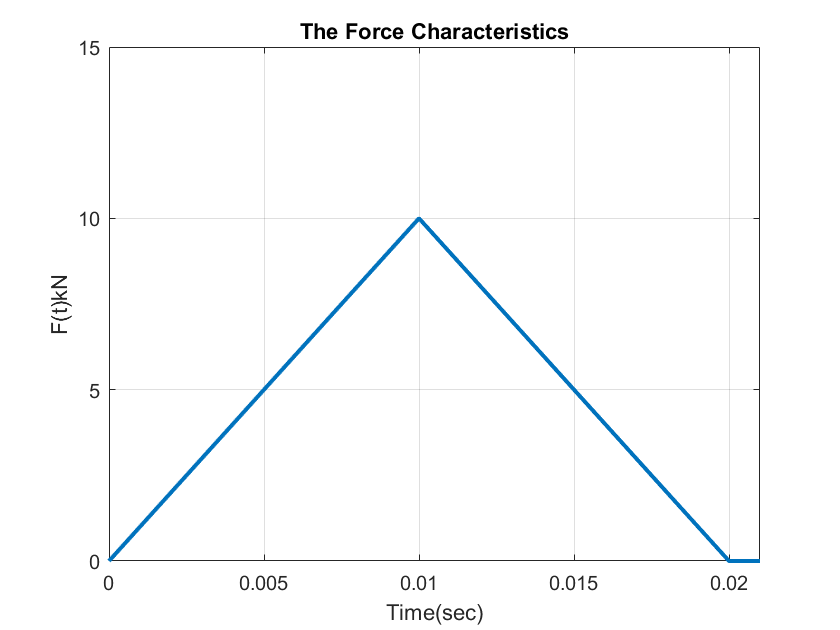

% Define force function
F = @(t) 1000*t.*(t<=0.01) + (20-1000*t).*(t>=0.01).*(t<=0.02);
fplot(F,[0,0.021],"LineWidth",2)
ylim([0,15])
xlabel("Time(sec)")
ylabel("F(t)kN")
grid on
title("The Force Characteristics")

Here is an outline of the steps you can follow:

- Define the problem parameters, such as the dimensions and material properties of the stepped bar, the force function, and the time step values.

- Divide the bar into finite elements and calculate the element properties, such as the length, stiffness matrix, and mass matrix.

- Assemble the global stiffness matrix and mass matrix by combining the element matrices using the nodal connectivity information.

- Set up the initial conditions for displacement and velocity at each node, and calculate the initial acceleration using the force function.

- Loop through the time steps and for each time step, do the following: a. Calculate the force vector at the current time step using the force function. b. Calculate the acceleration vector at the current time step using the current displacement, velocity, and force vectors, and the global stiffness and mass matrices. c. Update the displacement and velocity vectors at the current time step using the current displacement, velocity, and acceleration vectors, and the time step value.

- Plot the displacement and velocity of the free end (C) versus time for each of the three time step values, and compare the results.

# **Expressions:**

**For the stepped bar problem, each element was approximated as a beam element, and the stiffness and mass matrices were derived based on the properties of the element. The stiffness matrix represents the relationship between the forces applied to the element and the resulting deformations, while the mass matrix represents the distribution of mass within the element.**

Here are the expressions and values for the element stiffness matrix, mass matrix, and force vector for a 2-node linear element in the explicit dynamic finite element method:

**Element stiffness matrix:**

The element stiffness matrix is given by:


$$\left\lbrack \mathrm{K}\right\rbrack =\frac{\textrm{AE}}{\mathrm{L}}\left\lbrack \begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right\rbrack$$
  

where E is the Young's modulus, A is the cross-sectional area, and L is the element length. For the semi-conical section AB with diameters D1 and D2, the cross-sectional area A varies  linearly along the length of the element and can be expressed as:


$$A=\frac{{\pi D}^2 }{4}$$


where D varies linearly from D1 to D2 along the length of the element. For the cylindrical section BC with diameter D3, the cross-sectional area is:


$$A=\frac{{\pi D_3 }^2 }{4}$$


**Element mass matrix:**

The element mass matrix is given by:


$$\left\lbrack \mathrm{M}\right\rbrack =\frac{\rho \textrm{AL}}{2}\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


where $\rho$ is the density, A is the area, L is the length of the element, and me is the 4x4 mass matrix for the element.

**Element force vector:**

The element force vector is given by:


$$\left\lbrack \mathrm{F}\right\rbrack =\left\lbrack \begin{array}{c}
{\mathrm{f}}_1 \\
{\mathrm{f}}_2 
\end{array}\right\rbrack$$


where f1 and f2 are the nodal forces due to external loads and are given by:

 
$${\mathrm{f}}_1 =\frac{\mathrm{Q}}{2}$$



$${\mathrm{f}}_2 =\frac{\mathrm{Q}}{2}$$


where Q is the force applied at the free end of the bar. Note that the above expressions are for a 2-node linear element, and will need to be modified if higher-order elements are used.

## Stepped bar problem using explicit dynamic finite element analysis

## Define problem parameters

E = 200e9;              % Young's modulus (Pa)
rho = 7800;             % density (kg/m^3)
D1 = 40e-3;             % diameter of section AB (m)
D2 = 20e-3;             % diameter of section BC (m)
L1 = 4;                 % length of section AB (m)
L2 = 4;                 % length of section BC (m)
Fmax = 10e3;            % maximum force (N)
tmax = 0.02;            % maximum time (s)
dx = 0.2;   % element length
% Dt_cr = (2*dx*rho)/(sqrt(E/rho)); % stability criterion for explicit time integration
dt1 = 2e-5;             % time step for part (a) (s)
c = sqrt(E/rho);
dt2 = dx/c;     % time step for part (b) (s)
dt3 = 5e-5;             % time step for part (c) (s)
% Define force function
F = @(t) 1000.*t.*(t<=0.01) + (20-1000.*t).*(t>=0.01).*(t<=0.02);

% Divide bar into finite elements
nel1 = 20;              % number of elements in section AB
nel2 = 10;              % number of elements in section BC
Lel1 = L1/nel1;         % length of element in section AB (m)
Lel2 = L2/nel2;         % length of element in section BC (m)

## Area of section AB (m^2) (Frustum of a cone)

AreaAB = zeros(1,20)  % initialize the areas

AreaAB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Dia=[D1:-0.001:D2]      % diameters of each elements

Dia =     0.0400    0.0390    0.0380    0.0370    0.0360    0.0350    0.0340    0.0330    0.0320    0.0310    0.0300    0.0290    0.0280    0.0270    0.0260    0.0250    0.0240    0.0230    0.0220    0.0210    0.0200


for j=1:20
    AreaAB(j) =(pi/4)*(Dia(j)^2 + Dia(j+1)^2)/2;
end
AreaAB

AreaAB =     0.0012    0.0012    0.0011    0.0010    0.0010    0.0009    0.0009    0.0008    0.0008    0.0007    0.0007    0.0006    0.0006    0.0006    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003


## Area of section BC (m^2)

AreaBC = zeros(1,10);  % initialize the areas
for j = 1:10
    AreaBC(j) = (pi*D2^2)/4 ;
end 
AreaBC

AreaBC = 	1.0e+-3 *

    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142


## Mass and Stiffness matrix for section AB

ke1 = cell(1,20);
me1 = cell(1,20);

    for j =1:20
        ke1{j} = (E*AreaAB(j)/Lel1)*[1,-1;-1,1]; 
        me1{j} =((rho*AreaAB(j)*Lel1)/2)*[1,0;0,1];
    end
ke1

ke1 = 1×20 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}


me1

me1 = 1×20 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}


## Mass and Stiffness matrix for section BC

ke2 = cell(1,10);
me2 = cell(1,10);
    for j =1:10
        ke2{j} = (E*AreaBC(j)/Lel2)*[1,-1;-1,1]; 
        me2{j} =((rho*AreaBC(j)*Lel2)/2)*[1,0;0,1];
    end
ke2

ke2 = 1×10 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}


##  Assemble global stiffness and mass matrices For Step 1

K = zeros((nel1+nel2+1)); % global stiffness matrix
M = zeros((nel1+nel2+1)); % global mass matrix
%f = zeros(nel2+nel1+1, 1); % Global force vector

% Section AB
for i=1:20
    K(i:i+1,i:i+1) = K(i:i+1,i:i+1) + ke1{i};
    M(i:i+1,i:i+1) = M(i:i+1,i:i+1) + me1{i};
end
% Section AB to BC
for i=21:30
    for j=1:10
        
        K(i:i+1,i:i+1) = K(i:i+1,i:i+1) + ke2{j};
        M(i:i+1,i:i+1) = M(i:i+1,i:i+1) + me2{j};
        
    end
   
end


% Apply Boundary Condition
K(1,:) = 0;
K(1,1) = 1;
M(1,:) = 0;
M(1,1) = 1;

% Define time steps and initial conditions
nSteps1 = ceil(tmax/dt1);

u1 = zeros(nel1+nel2+1,nSteps1);  % Displacement vector
v1 = zeros(nel1+nel2+1,nSteps1);  % Velocity vector
a1 = zeros(nel1+nel2+1,nSteps1);  % Acceleration Vector

% Initial Conditions
u1(:,1) = 0;
v1(:,1) = 0;

% Central Difference Method
for i = 2:nSteps1
    % force vector at time i
    f = F((i).*dt1);
    % Solve for acceleration  at time i
    a1 = pinv(M)*(f - K*u1(:,i-1));
    % Update velocity and acceleration at time i
    v1(:,i) = v1(:,i-1)  + a1.*(dt1/2);
    u1(:,i) = u1(:,i-1) + v1(:,i).*dt1  + a1.*(dt1^2/4);
    % apply boundary conditions at each time step
    u1(1,i) = 0;
    v1(1,i) = 0;
end
% Extract displacement and velocity of free end (C)
uc1 = u1(end,1:end)

uc1 = 	1.0e+-5 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011


vc1 =v1(end,1:end)

vc1 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


## For Step 2:

% Define time steps and initial conditions
nSteps2 = ceil(tmax/dt2)

nSteps2 = 507


u2 = zeros(nel1+nel2+1,nSteps2);  % Displacement vector
v2 = zeros(nel1+nel2+1,nSteps2);  % Velocity vector
a2 = zeros(nel1+nel2+1,nSteps2);  % Acceleration Vector

% Initial Conditions
u2(:,1) = 0;
v2(:,1) = 0;

% Central Difference Method
for i = 2:nSteps2
    % force vector at time i
    f = F((i).*dt2);
    % Solve for acceleration  at time i
    a2 = pinv(M)*(f - K*u2(:,i-1));
    % Update velocity and acceleration at time i
    v2(:,i) = v2(:,i-1)  + a2.*(dt1/2);
    u2(:,i) = u2(:,i-1) + v2(:,i).*dt1  + a2.*(dt1^2/4);
    % apply boundary conditions at each time step
    u2(1,i) = 0;
    v2(1,i) = 0;
end
% Extract displacement and velocity of free end (C)
uc2 = u2(end,1:end)

uc2 = 	1.0e+-5 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021


vc2 =v2(end,1:end)

vc2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001


## For Step 3

% Define time steps and initial conditions
nSteps3 = ceil(tmax/dt3)

nSteps3 = 400


u3 = zeros(nel1+nel2+1,nSteps3);  % Displacement vector
v3 = zeros(nel1+nel2+1,nSteps3);  % Velocity vector
a3 = zeros(nel1+nel2+1,nSteps3);  % Acceleration Vector

% Initial Conditions
u3(:,1) = 0;
v3(:,1) = 0;

% Central Difference Method
for i = 2:nSteps3
    % force vector at time i
    f = F((i).*dt2);
    % Solve for acceleration  at time i
    a3 = pinv(M)*(f - K*u3(:,i-1));
    % Update velocity and acceleration at time i
    v3(:,i) = v3(:,i-1)  + a3.*(dt1/2);
    u3(:,i) = u3(:,i-1) + v3(:,i).*dt1  + a3.*(dt1^2/4);
    % apply boundary conditions at each time step
    u3(1,i) = 0;
    v3(1,i) = 0;
end
% Extract displacement and velocity of free end (C)
uc3 = u3(end,1:end)

uc3 = 	1.0e+-5 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021


vc3 =v3(end,1:end)

vc3 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001


## For The First Time Step

#### Plot displacement and velocity versus time  at end C

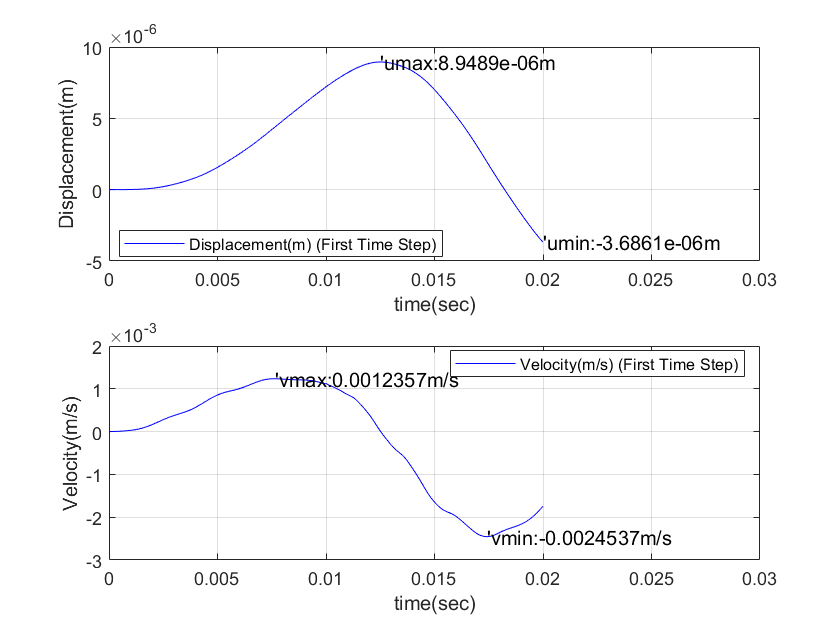

figure(1)
subplot(2,1,1)
% displacement
time1 = linspace(0,0.02,nSteps1);
plot(time1, uc1,"b","LineWidth",0.5)
text(time1(uc1==max(uc1)),max(uc1),['''umax:', num2str(max(uc1)) 'm'])
text(0.02,min(uc1),['''umin:', num2str(min(uc1)) 'm'])
xlabel("time(sec)")
ylabel("Displacement(m)")
legend("Displacement(m) (First Time Step)","Location","best")
grid on
xlim([0,0.03])

subplot(2,1,2)
% velocity
plot(time1, vc1,"b","LineWidth",0.5)
text(time1(vc1==max(vc1)),max(vc1),['''vmax:', num2str(max(vc1)) 'm/s'])
text(time1(vc1==min(vc1)),min(vc1),['''vmin:', num2str(min(vc1)) 'm/s'])
xlabel("time(sec)")
ylabel("Velocity(m/s)")
legend("Velocity(m/s) (First Time Step)","Location","best")
grid on
xlim([0,0.03])

## Comments

The plot shows that there is no displacement and velocity from the starting points. 

Towards the end points, the bar appears to move and the velocity response was very fast.

## For the second time step

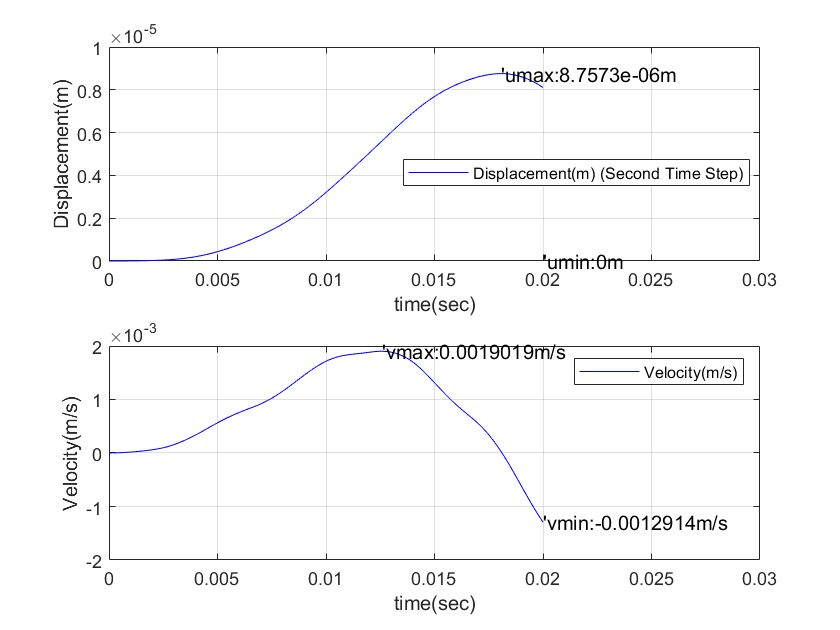

% Plot displacement and velocity versus time at C
figure(2);
subplot(2,1,1)
% displacement
time2 = linspace(0,0.02,nSteps2);
plot(time2, uc2,"b","LineWidth",0.5)
text(time2(uc2==max(uc2)),max(uc2),['''umax:', num2str(max(uc2)) 'm'])
text(0.02,min(uc2),['''umin:', num2str(min(uc2)) 'm'])
xlabel("time(sec)")
ylabel("Displacement(m)")
legend("Displacement(m) (Second Time Step)","Location","best")
grid on
xlim([0,0.03])

subplot(2,1,2)
% velocity
plot(time2, vc2,"b","LineWidth",0.5)
text(time2(vc2==max(vc2)),max(vc2),['''vmax:', num2str(max(vc2)) 'm/s'])
text(time2(vc2==min(vc2)),min(vc2),['''vmin:', num2str(min(vc2)) 'm/s'])
xlabel("time(sec)")
ylabel("Velocity(m/s)")
legend("Velocity(m/s)")
grid on
xlim([0,0.03])

## Comments:

The plots show that the bar displacement  reaches the steady state point very faster than that of the first time step.

## For The Third time step

#### Plot displacement and velocity versus time for end C

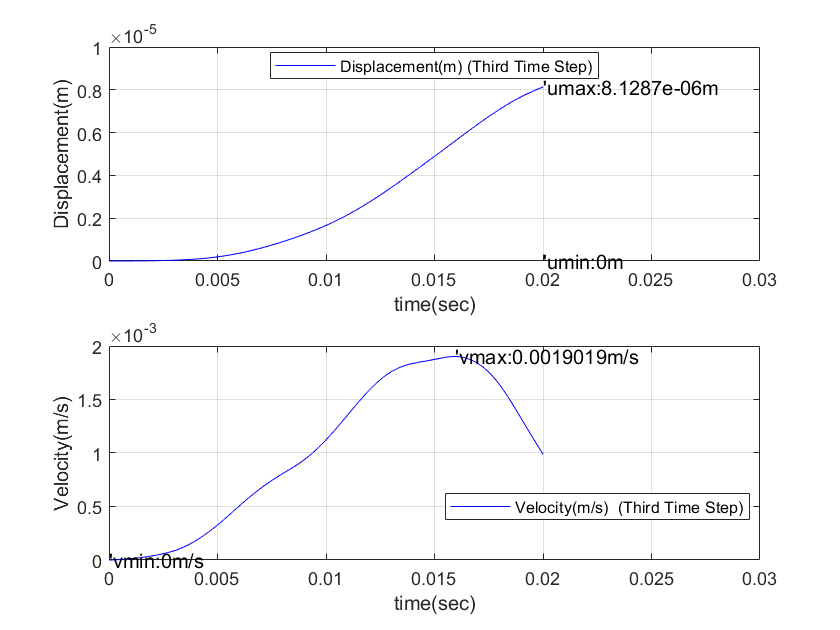

figure(3);
subplot(2,1,1)
% displacement
time3 = linspace(0,0.02,nSteps3);
plot(time3, uc3,"b","LineWidth",0.5)
text(time3(uc3==max(uc3)),max(uc3),['''umax:', num2str(max(uc3)) 'm'])
text(0.02,min(uc3),['''umin:', num2str(min(uc3)) 'm'])
xlabel("time(sec)")
ylabel("Displacement(m)")
legend("Displacement(m) (Third Time Step)","Location","best")
grid on
xlim([0,0.03])

subplot(2,1,2)
% velocity
plot(time3, vc3,"b","LineWidth",0.5)
text(time3(vc3==max(vc3)),max(vc3),['''vmax:', num2str(max(vc3)) 'm/s'])
text(time3(vc3==min(vc3)),min(vc3),['''vmin:', num2str(min(vc3)) 'm/s'])
xlabel("time(sec)")
ylabel("Velocity(m/s)")
legend("Velocity(m/s)  (Third Time Step)","Location","best")
grid on
xlim([0,0.03])

## Comments

The displacement appears to be increasing gradually towards the end point of the bar.

The velocity appears to be steady from the starting point and it behaves sinusoidally towards the stopping time.